# Clear console and workspace and add project root to path

close all;
project_root='/home/predator/swarmlab';
addpath(genpath(project_root));

## Call parameters files and initialisation variables

PATH_COMPLETED = false;
MOBILITY_MODEL = 1; 
ROTATIONAL_MODEL=0;
DRONE_TYPE="quadcopter";
SIMULATION_REALISTIC= true;
ACTIVE_ENVIRONMENT = false;
DEBUG = false;
VIDEO = false;
CENTER_VIEW_ON_SWARM = true;
fontsize = 12;
run('param_sim.m');
run('param_battery');
run('param_physics');
run('param_swarm');
run('param_GS.m');

p_GS.Mx=8;
p_GS.My=8;
FREQ= p_GS.freq;

if DRONE_TYPE == "fixed_wing" || DRONE_TYPE == "quadcopter"
    run('param_drone.m');
elseif DRONE_TYPE == "point_mass"
    run('param_drone.m');
end
run('param_map');

if DRONE_TYPE == "point_mass"
    SWARM_VIEWER_TYPE = "agent";
elseif DRONE_TYPE == "quadcopter"
    SWARM_VIEWER_TYPE = "drone";
end

## Init Swarm object, Wind, Viewer and other variables

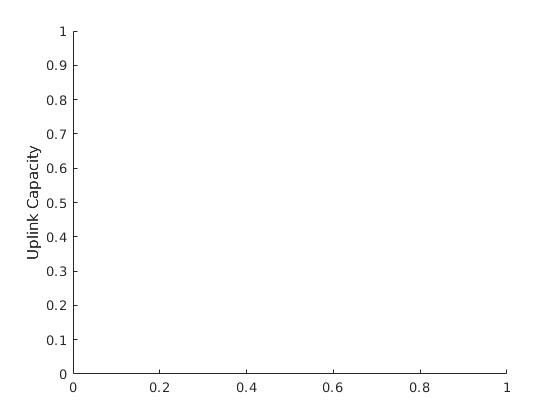

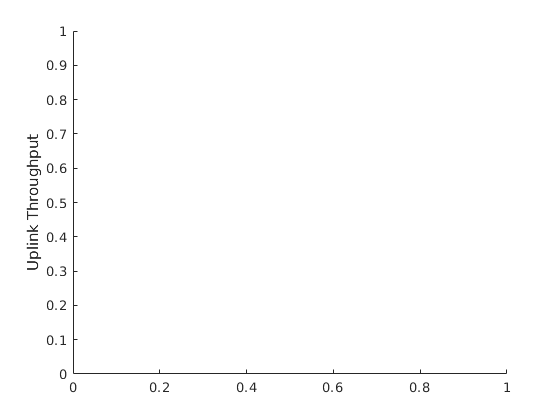

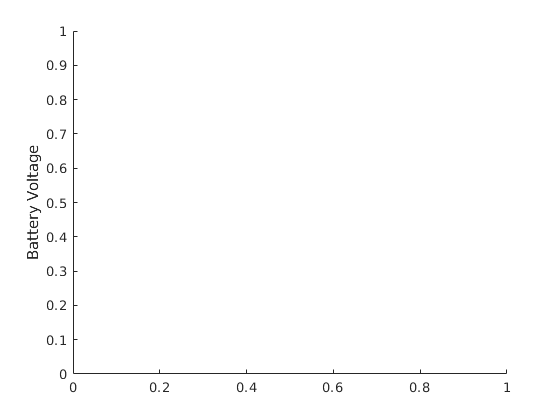

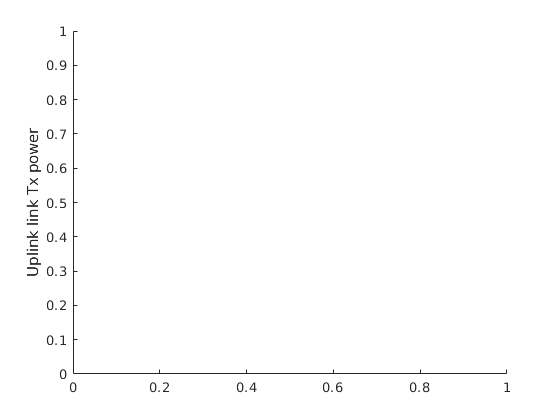

% Init swarm and set positions
scale=0.1;
x1=-3000*scale;
x2=6000*scale;
y1=4000*scale;
y2=12000*scale;
GSD=(2e-1)*scale;
FL=(5e-3)*scale;
PS=(2.3e-6)*scale;

swarm = Swarm();
% swarm.algorithm = SWARM_ALGORITHM;
drones_x=5;
drones_y=4;
p_swarm.nb_agents=drones_y*drones_x;
%swarm.nb_agents=p_swarm.nb_agents;
swarmpos=[];
for i = 1 : p_swarm.nb_agents
    swarm.add_drone(DRONE_TYPE, p_drone, p_battery, p_sim, p_physics,map);
end
swarm.add_GS(p_GS.Mx,p_GS.My, p_GS.Az, p_GS.El,p_GS.freq,p_GS.N0,p_GS.bw,p_GS.pu);
for j=1:drones_y
    for i=1:drones_x
%         x=x1+(i-1)*((x2-x1)/5);
%         y=y1+(j*(y2-y1)/4);
%         z=0;
        k=5*(j-1)+i;
        swarmpos(:,k)=[x1+(i-1)*((x2-x1)/5);y1+(j*(y2-y1)/4);0];
    end
end
swarm.set_pos(swarmpos)
% Init wind
wind = zeros(6,1); % steady wind (1:3), wind gusts (3:6)

% Init viewer
swarm_viewer = SwarmViewer(p_sim.dt_plot, CENTER_VIEW_ON_SWARM);
swarm_viewer.viewer_type = SWARM_VIEWER_TYPE;
states_handle = [];
%plot variables
if MOBILITY_MODEL ==1 && ROTATIONAL_MODEL ==1
    omega=2*pi/3;
    inclination=[0,0,0];
    f6=figure;
    h1=animatedline('Color','g');
    h2=animatedline('Color','r');
    h3=animatedline('Color','b');
    xlabel("time")
    ylabel("orientation in radians")
    hold on
    ind=1;
end

if MOBILITY_MODEL ==1 
 colour={'#FF0000','#00FF00','#0000FF','#00FFFF','#FF00FF','#FFFF00','#000000','#0072BD','#D95319','#EDB120','#7E2F8E','#77AC30','#4DBEEE','#A2142F'};
f1=figure;
up_c=gobjects(swarm.nb_agents,1);
for i=1:swarm.nb_agents
    up_c(i)=animatedline('color',string(colour(mod(i,14)+1)));
end
ylabel("Uplink Capacity");
%legend({'Drone1','Drone2','Drone3','Drone4','Drone5','Drone6','Drone7','Drone8','Drone9','Drone10','Drone11','Drone12'});
hold on
f2=figure;
up_t=gobjects(swarm.nb_agents,1);
for i=1:swarm.nb_agents
    up_t(i)=animatedline('color',string(colour(mod(i,14)+1)));
end
ylabel("Uplink Throughput");
hold on
f3=figure;
b_l=gobjects(swarm.nb_agents,1);
for i=1:swarm.nb_agents
    b_l(i)=animatedline('color',string(colour(mod(i,14)+1)));
end
ylabel("Battery Voltage");
hold on
f4=figure;
up_p=gobjects(swarm.nb_agents,1);
for i=1:swarm.nb_agents
    up_p(i)=animatedline('color',string(colour(mod(i,14)+1)));
end
ylabel("Uplink link Tx power");
hold on
%Plot of drone path
f5=figure;
d_t=gobjects(swarm.nb_agents,1);
for i=1:swarm.nb_agents
    d_t(i)=animatedline('color',string(colour(mod(i,14)+1)));
end
ylabel("Drone trajectory");
hold on
legend({'Drone1','Drone2','Drone3','Drone4','Drone5','Drone10','Drone15','Drone20'});
end

## Main simulation loop

h1=animatedline;
kp=[1,1,0.4];
ki=[0,0,0];
kd=[2,2,2];
vel=zeros(1,3);
error=zeros(1,3);
error_prev=zeros(1,3);
error_sum=zeros(1,3);
error_diff=zeros(1,3);
velsat=10;
threshold=1;
disp('Type CTRL-C to exit');

Type CTRL-C to exit


equivalent_drone = swarm.get_barycenter();
%waypoints=get_waypoints(equivalent_drone.pos_ned',drones_x,drones_y,x1,x2,y1,y2,GSD,FL,PS);
%addpoints(h1,waypoints(:,2),waypoints(:,1),-waypoints(:,3))
%hold on
waypoints=[65,930,30];
j=1;
display(equivalent_drone.pos_ned);

    60
   900
     0



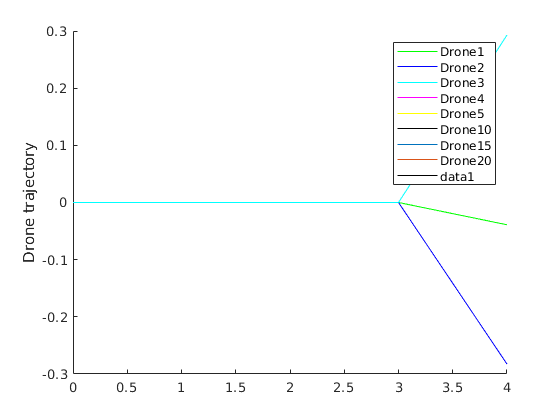

for time = p_sim.start_time: p_sim.dt:5
    
    if ( MOBILITY_MODEL == 1 )
        %%%%%%%%%%%%%%%%%%%%%%%   SURVEILLANCE MODEL %%%%%%%%%%%%%%%%%%%%%%%%%%%
        if PATH_COMPLETED == false
            if norm(equivalent_drone.pos_ned.'-waypoints(j,:)) <= threshold
                j=j+1;
            end
            if j>length(waypoints(:,1))
                PATH_COMPLETED= true;
                waypoints(j,:)=mean(swarmpos,2);
                break; 
            end
        end
        if ROTATIONAL_MODEL ==1
            inclination(1,ind)=mod((inclination(1,ind)+(omega*p_sim.dt)),2*pi);
            equivalent_drone.attitude(ind,1)=inclination(1,ind);
            degree=equivalent_drone.attitude(ind,1);
            if inclination(1,ind) == 0
                ind=mod(ind,3)+1;
            end
            addpoints(h1,time,equivalent_drone.attitude(1,1));
            addpoints(h2,time,equivalent_drone.attitude(2,1));
            addpoints(h3,time,equivalent_drone.attitude(3,1));
            drawnow update;
            hold on;
        end
            error=waypoints(j,:)-equivalent_drone.pos_ned';
            error_diff=error-error_prev;
            error_sum=error_sum+error;
            vel=kp.*error + ki.*error_sum + kd.*error_diff;
            error_prev=error;
            k=vel>velsat;
            vel(k)=velsat;
            k=vel<-velsat;
            vel(k)=-velsat;
            vel=-vel;
            swarm.set_velocity_commands([0,-vel(1),-vel(2),-vel(3)]);
            swarm.update_state(wind, time , p_GS.freq);
            equivalent_drone = swarm.get_barycenter();
            
            %Plotting every 1 second
            if mod(time,1)==0
%                 uplinkcapacity=swarm.get_uplink_capacity(p_GS.freq);
%                 uplinkThroughput=swarm.get_uplinkThroughput(p_GS.Bc,velsat,p_GS.freq,p_GS.tau_dl,p_GS.tau_ctrl);
%                 uplinkTxpower=swarm.get_uplinkTransmitpower(p_GS.freq);
%                 for i=1:swarm.nb_agents
%                     addpoints(up_c(i), time , uplinkcapacity(i));
%                     addpoints(up_t(i),time,uplinkThroughput(i));
%                     addpoints(b_l(i),time,swarm.drones(i).V);
%                     addpoints(up_p(i),time,uplinkTxpower(i));
%                 end
                
                addpoints(d_t(1),time,swarm.drones(1).attitude(3));
                addpoints(d_t(2),time,swarm.drones(1).attitude(2));
                addpoints(d_t(3),time,swarm.drones(1).attitude(1));
            %Drone trajectory plot
%                 for i=1:swarm.nb_agents
%                     addpoints(d_t(i),swarm.drones(i).pos_ned(1),swarm.drones(i).pos_ned(2),swarm.drones(i).pos_ned(3))
%                 end
                drawnow update;
                hold on;
            end
     end
end


display("Simulation Finished")

% Close all plots%
%close all;




